# Filter Design

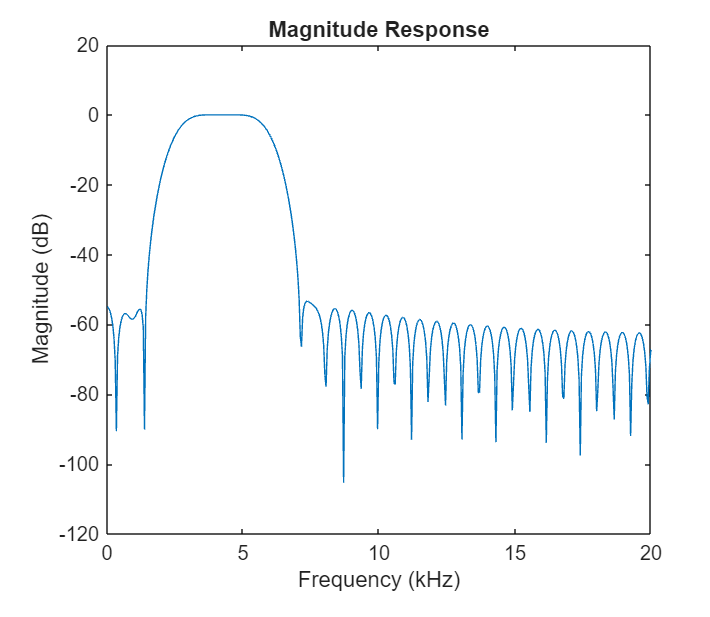

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB® Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB. To work through this script, it will also be useful to have an understanding of convolution. If you need more instruction or just a refresher, consider taking a look at [this live script](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Convolution-Digital-Signal-Processing&project=Convolution.prj&file=ConvolutionFilters.mlx) on convolution and filtering.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understaning of those concepts and may be used for grading and completion checks by your professor.

## Impulse responses

In the previous live script, you learned about a few types of filters: highpass, lowpass, bandpass, and bandstop. Now it's time to get more granular by learning about *impulse responses*. An impulse response can be defined as the way a system reacts to a brief input signal that occurs at a single point in time. For example, imagine that somebody claps their hands once inside a room. The initial clap can be classified as the *impulse*, and the sound produced by the clap can be considered the *impulse response*. It is important to note that the same clap could produce a different sound depending on the acoustics of the space in which it occurs; similarly, the same impulse can produce a different impulse response depending on the system it occurs within.

  **Try**. Why might the impulse response of a filter be important? What can it tell you about the filter? Run the line of code below to reveal some reasons why impulse responses are important:

Reveal

You will see the importance of impulse responses in action in the following section.

## Finite Impulse Response (FIR) filters

FIR filters are digital filters with a finite number of nonzero impulse response values. FIR filters do not use feedback, meaning that the input of the filter does not depend on its output.

FIR filters are inherently stable because their impulse response "dies out" after a certain number of samples. This makes them particularly useful in applications where stability is critical.

The next section of this script will walk you through how FIR filters work in practice.

### FIR filter example

  **Try**. Let's start by generating a simple sine wave signal with some noise. Run the code below to do this.

% Define a fundamental frequency of 100Hz and a sampling frequency of 48,000Hz
FundamentalFreq = 100;
SamplingFreq = 48000;

% Create a sine signal with random noise
N = 500;
TimeVec = (1 / SamplingFreq) * (0:N-1)';
SineSig = 0.2 * sin(2 * pi * FundamentalFreq * TimeVec) + 0.01 * randn(size(TimeVec));

% Plot the sine signal
PlotSineSig(TimeVec, SineSig);

Now, we'll design a very simple FIR filter and apply it to this noisy sine wave. The simplest type of FIR filter can also be called a *moving average filter*, which is similar to the Savitzky-Golay filter you saw in [FilteringIntro.mlx](matlab:open('Scripts/FilteringIntro.mlx')). It simply filters the signal by averaging a particular number of recent input values to calculate a new output value.

  **Try**. Read through the code and associated comments below to understand how the filter is created. Then run the code to view the associated impulse response.

% Define filter order of 51
N = 51;

% Create simple moving average FIR filter
SimpleFIR = (1 / N) * ones(1, N);

% Plot the impulse response of the filter
impz(SimpleFIR)

 **Reflect**. What do you notice about this impulse response? Why do you think it looks like this?

You should have noticed that the impulse response was simply a set of constant values. This is because a moving average filter is a specific case of FIR filter where all coefficients are equal and sum to one. For an FIR filter, the impulse response is identical to the filter coefficients. Therefore, the way the impulse response relates to the filter itself is that the output signal is just the result of a convolution operation between the input signal and the impulse response (or filter coefficients). If you need a refresher on convolution as it relates to filtering, check out this [live script](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Convolution-Digital-Signal-Processing&project=Convolution.prj&file=ConvolutionFilters.mlx).

The `filter` function in MATLAB can be used to apply a 1-D digital filter to a signal. The syntax of the function is as follows:

where `b` represents the numerator coefficients of the filter, `a` represents the denominator coefficients, and `x` represents the signal to be filtered.

  **Try**. Fill in the arguments of the `filter` function below, keeping in mind that the numerator coefficients for your filter are stored in `SimpleFIR`, the denominator is 1, and the signal to be filtered is `SineSig`. Then, run the code to apply this simple FIR filter to the noisy sine signal and plot the results to see its effects.

% FILL IN THE ARGUMENTS TO THE FILTER FUNCTION
FilteredSineSig = filter();

% Plot the filtered sine signal over the original sine signal
PlotFilteredSineSig(TimeVec, SineSig, FilteredSineSig);

 **Reflect**. Why do you think the two signals are not lined up?

### Group delay

You should have noticed in the plot above that the filtered signal is not aligned with the original signal on the x-axis. This is due to an effect called *group delay*, which is the time it takes for a signal to pass through the filter. For FIR filters, group delay is constant, meaning that while the filtered signal will not line up perfectly with the original signal on the x-axis, the shape of the signal will be maintained. Verify this by running the line of code below.

  **Try**. Run the line of code below, which plots the group delay of the filter we just designed.

grpdelay(SimpleFIR);

### Application to birdsong signal

To see how all of these concepts work in a real-world application, let's bring back the [birdsong signal from the previous script](matlab:open('./FilteringIntro.mlx')).

  **Try**. Run the code below to load the signal.

% Read in the birdsong signal
[Signal, SamplingFreq] = audioread("BirdSong.m4a");

% Take a reasonably sized portion of the signal
Signal = Signal(236906:673812,2);
disp("Data loaded")

The code below will design a simple bandpass FIR filter, similar to the one you created in the previous script. It will use 2.5 kHz as the lower passband frequency and 6 kHz as the upper bandpass frequency.

  **Try**. Use the slider below to change the order of the filter. When you move the slider, you will see how it affects the impulse response and group delay, and something called the *magnitude response* of the filter.

% Define the Nyquist frequency as half of the sampling frequency
NyquistFreq = SamplingFreq / 2;

% Create an FIR filter with order as defined by the slider and frequency limits of 2500Hz and 6000Hz
bFIR = fir1(1, [2500/NyquistFreq 6000/NyquistFreq]);

% Plot impulse response, group delay, and magnitude response
PlotResponsesFIR(bFIR, SamplingFreq);

 **Reflect**. Based on these plots, how does the filter order affect the magnitude response?

 **Exercise 1. **Based on the plots above and how they change with different filter orders, what does the magnitude response of a filter represent? Select exactly one answer.

            A. The time delay introduced by the filter at various frequencies

            B. The amount of magnitude amplification or attenuation the filter applies to different frequencies

            C. The speed at which the filter operates on an input signal

            D. The phase shift that the filter applies to different frequencies

A = false; B = false; C = false; D = false;
 
CheckExercise1(A, B, C, D);

 **Exercise 2. **Based on the plots above, what does the central point of the impulse response of an FIR filter represent? Select exactly one answer. *Note: This only applies to FIR filters because their impulse response is symmetrical. You will see later in this script that this is not the case for all filters.*

            A. The peak of the filter's magnitude response

            B. The filter's minimum attenuation level

            C. The constant value of the group delay of the filter

            D. The point at which the filter's group delay is zero

A = false; B = false; C = false; D = false;
 
CheckExercise2(A, B, C, D);

## Infinite Impulse Response (IIR) filters

IIR filters are a type of digital filter that has an impulse response which continues indefinitely without converging to zero. Unlike FIR filters, they are designed using feedback, meaning that the output of the filter is fed back into the input. This feedback loop creates a filter that can have an infinite response to a finite input.

### Application to birdsong signal

Let's design an IIR filter and apply it to the birdsong signal the same way you just did with an FIR filter. This way, you can compare the pros and cons of each type of filter.

*If you haven't already loaded the birdsong signal, run **this code** to do so.*

The code below will design a simple bandpass IIR filter called a *Butterworth filter*. Like the one in the section above, it will use 2.5 kHz as the lower passband frequency and 6 kHz as the upper bandpass frequency.

The `butter` function in MATLAB can be used to apply a Butterworth filter to a signal. The syntax of the function is as follows:

where `n` represents the filter order and `Wn` represents the cutoff frequency of the filter.

  **Try**. Fill in the arguments of the `butter` function below, remembering that the filter order is set by the slider below and is stored in `FilterOrder` and the cutoff frequency is the same as in the section above, which can be written as:

Then, use the slider to change the order of the filter. When you move the slider, you will see how it affects the impulse response, group delay, and magnitude response of the filter.

% Define the filter order
FilterOrder = 1;

% Define the Nyquist frequency as half of the sampling frequency
NyquistFreq = SamplingFreq / 2;

% FILL IN THE ARGUMENTS TO THE BUTTER FUNCTION
[bIIR, aIIR] = butter();

% Plot impulse response, group delay, and magnitude response
PlotResponsesIIR(bIIR, aIIR, SamplingFreq, FilterOrder);

 **Reflect**. You may have noticed that the options for filter order are much smaller than they were for FIR filters. This is because IIR filters are able to achieve similar results with a much lower filter order.

 **Exercise 3. **Comparing the group delay plot for the IIR filter above to the group delay plot for the FIR filter in the previous section, which of the following are true? Select all answers that apply.

            A. The group delay for an FIR filter is constant, while the group delay for an IIR filter is not

            B. The group delay for an IIR filter is constant, while the group delay for an FIR filter is not

            C. The group delay for a filter is never constant

            D. The group delay for an IIR filter is very low at frequencies outside the passband, but much higher at frequencies inside the passband

A = false; B = false; C = false; D = false;
 
CheckExercise3(A, B, C, D);

 **Exercise 4. **For each of the following statements, write either **FIR** or **IIR** in the corresponding text box below. Use the results from the previous activities to inform your answers. Click the **Submit** button when you are finished.

            A. This type of filter is able to achieve similar results while using a lower filter order

            B. This type of filter is able to achieve a constant group delay

            C. This type of filter is inherently stable because it does not rely on feedback to calculate its output values

A = "";
B = "";
C = "";
 
CheckExercise4(A, B, C);

## Design Filter Live Task

In the code section below, you will insert a *Live Task* that allows you to generate MATLAB code using an interactive interface. With everything you now know about filters and filter design, you should be able to use this Live Task to design a filter of your own. 

  **Try**. First, ensure that your cursor is in the empty code section below. Then, click the Task dropdown in the Code section of the MATLAB toolstrip. Search for "design filter" in the search bar and select the Design Filter icon as shown in the following screenshot. Once you have done this, the Live Task will appear in the code section below.

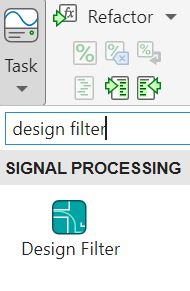

### Use the Live Task

To design the filter, simply explore the changes you can make in the Live Task and set them to your liking, then click the **Run** button   in the top right corner (or, if the **Autorun** check box is selected, it will run on its own).

  **Try**. Use the Live Task above to play around with designing different types of filters and visualizing their responses, including impulse response and magnitude response. In the code section below, you will be able to apply your designed filter to the birdsong signal and view the spectrogram of the filtered signal.

### Once you have designed your filter

  **Try**. Now that you have designed your filter, run the following code to apply it to the birdsong signal and view the spectrogram of the filtered signal. Before running the code, make sure that your filter is called `designedFilter` (this is the default name that the Live Task will use).

% Clear earlier figures
clf

% Load in the birdsong signal
[Signal, SamplingFreq] = audioread("BirdSong.m4a");
Signal = Signal(236906:673812,2);

% Filter the birdsong signal using the designed filter
FilteredSignal = filtfilt(designedFilter, Signal);

% Plot the spectrogram of the filtered signal
pspectrum(FilteredSignal, SamplingFreq, 'spectrogram');

## Local Helper Functions

**Reveal**

function Reveal
    fprintf("- By knowing the impulse response, you can predict how the filter will affect any signal.\n" + ...
        "- Impulse responses allow you to simplify your analysis of a filter by analyzing how they react to a simple impulse, rather than a more complex signal.\n" + ...
        "- You can design filters more effectively by shaping the impulse response to achieve the specific task you are working on.");
end

**CheckExercise1**

function CheckExercise1(A, B, C, D)
    if B && ~(A || C || D)
        disp("Correct! Great job");
    elseif A + B + C + D > 1
        disp("Please select just one answer");
    elseif A + B + C + D < 1
        disp("Please select an answer");
    else
        disp("Incorrect." + newline + "Hint: Look at the axes labels of the magnitude response plot to determine what is being measured");
    end
end

**CheckExercise2**

function CheckExercise2(A, B, C, D)
    if C && ~(A || B || D)
        disp("Correct! Great job");
    elseif A + B + C + D > 1
        disp("Please select just one answer");
    elseif A + B + C + D < 1
        disp("Please select an answer");
    else
        disp("Incorrect." + newline + "Hint: Look at the x-axis value of the impulse response's central point." + newline + "Does that value align to any values on the other plots?");
    end
end

**CheckExercise3**

function CheckExercise3(A, B, C, D)
    if A && D && ~(B || C)
        disp("Correct! Great job");
    elseif A + B + C + D < 1
        disp("Please select at least one answer");
    elseif A && ~D || D && ~A
        disp("You have selected one correct answer, but you are missing another." + newline + "What else do you notice about the group delay plots for the filters you designed?")
    else
        disp("Incorrect." + newline + "Hint: What is different about the group delay plots for the FIR and IIR filters you designed?" + newline + "When the group delay is not constant, how does it fluctuate?");
    end
end

**CheckExercise4**

function CheckExercise4(A, B, C)
    if A == "IIR" && B == "FIR" && C == "FIR"
        disp("Correct! Great job");
    elseif (A == "IIR" || A == "FIR") && (B == "IIR" || B == "FIR") && (C == "IIR" || C == "FIR")
        disp("Incorrect. Review the previous activities to refine your answers.");
    else
        disp("Make sure that your answer to each question is either FIR or IIR.");
    end
end

**PlotSineSig**

function PlotSineSig(TimeVec, SineSig)
    plot(TimeVec, SineSig)
    title('Simple Sine Wave');
    xlabel('Time');
    ylabel('Amplitude');
    xlim([0 TimeVec(end)]);
end

**PlotFilteredSineSig**

function PlotFilteredSineSig(TimeVec, SineSig, FilteredSineSig)
    plot(TimeVec, SineSig);
    hold on;
    plot(TimeVec, FilteredSineSig);
    hold off;
    legend(["Original signal", "Filtered signal"]);
    xlim([0 TimeVec(end)]);
end

**PlotResponsesFIR**

function PlotResponsesFIR(bFIR, SamplingFreq)
    f = figure('Position', [0 0 1700 400]);
    gd = grpdelay(bFIR, 1, 512);
    subplot(1,3,1);
    impz(bFIR, 1, gd(1)*2);
    subplot(1,3,2);
    grpdelay(bFIR, 1, 0:20000, SamplingFreq);
    subplot(1,3,3);
    [h,w] = freqz(bFIR, 1, 512, SamplingFreq);
    plot(w/1000,20*log10(abs(h)));
    xlim([0 20]);
    title('Magnitude Response');
    xlabel('Frequency (kHz)');
    ylabel('Magnitude (dB)');
end

**PlotResponsesIIR**

function PlotResponsesIIR(bIIR, aIIR, SamplingFreq, FilterOrder)
    f = figure('Position', [0 0 1700 400]);
    subplot(1,3,1);
    impz(bIIR, aIIR, 20 * FilterOrder);
    subplot(1,3,2);
    grpdelay(bIIR, aIIR, 0:20000, SamplingFreq);
    subplot(1,3,3);
    [h,w] = freqz(bIIR, aIIR, 20 * FilterOrder, SamplingFreq);
    plot(w/1000,20*log10(abs(h)));
    xlim([0 20]);
    title('Magnitude Response');
    xlabel('Frequency (kHz)');
    ylabel('Magnitude (dB)');
end